
clear,clc;
warning('off','all');
%% params

% Wphi = 1        
% Wp = 1   

Wphi = 0       

Wphi = 0

Wp = 0

Wp = 0

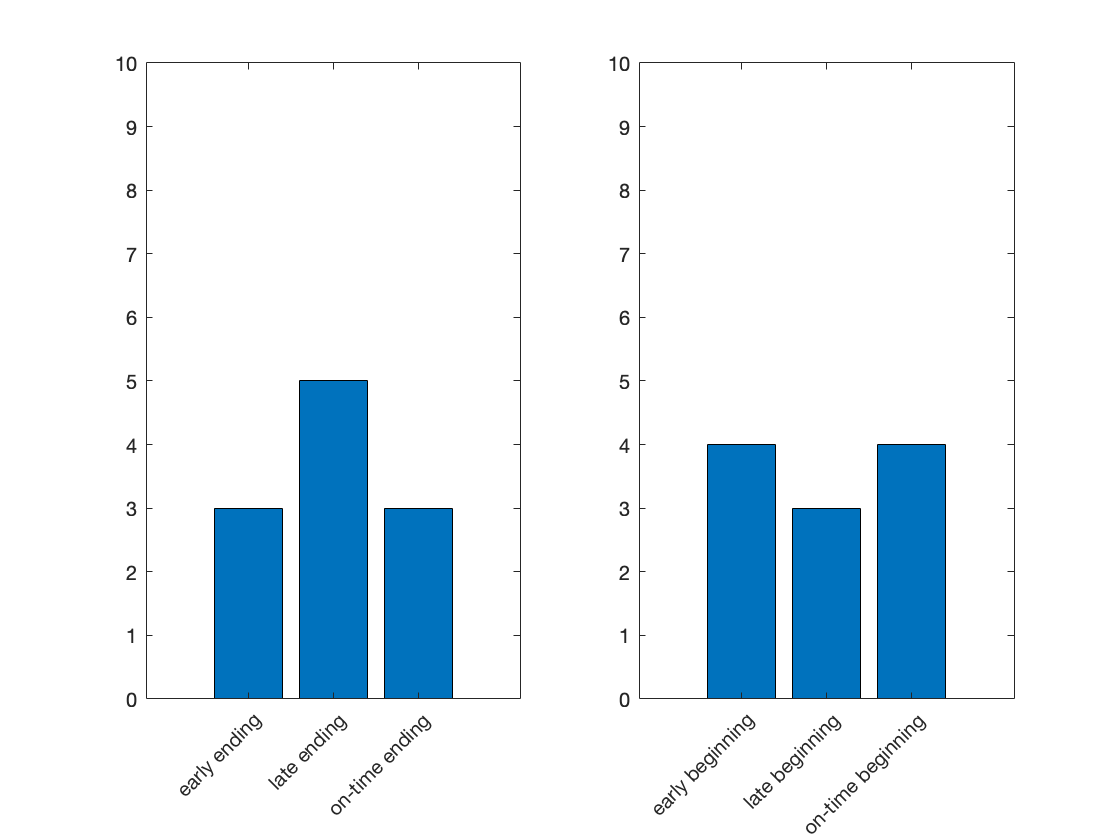



condits = OSCmodel_asfunc(Wphi, Wp);

beg_manipulation = groupsummary(condits, {'cmp_beg'},'sum', {'corr_resp'} );
end_manipulation = groupsummary(condits, {'st_end'},'sum', {'corr_resp'} );

% plot
figure;
subplot(1,2,1)
bar(end_manipulation.sum_corr_resp); 
xticklabels(table2cell(end_manipulation(:,1)));xtickangle(45);
yline(10); %set(gca, 'FontSize', 14);

subplot(1,2,2)
bar(beg_manipulation.sum_corr_resp); 
xticklabels(table2cell(beg_manipulation(:,1)));xtickangle(45);
yline(10); %set(gca, 'FontSize', 14);